**Load input image**

img = imread('Fig0442(a)(characters_test_pattern).tif'); 
[M, N] = size(img);

Define cutoff frequencies

D0_values = [10, 30, 60, 160, 460];

**Create frequency coordinates**

[U, V] = meshgrid(-N/2:N/2-1, -M/2:M/2-1);
D = sqrt(U.^2 + V.^2);

**Compute FFT of the image**

img_fft = fftshift(fft2(img));

**Apply ideal Pow Pass Filter and display the original image and results**

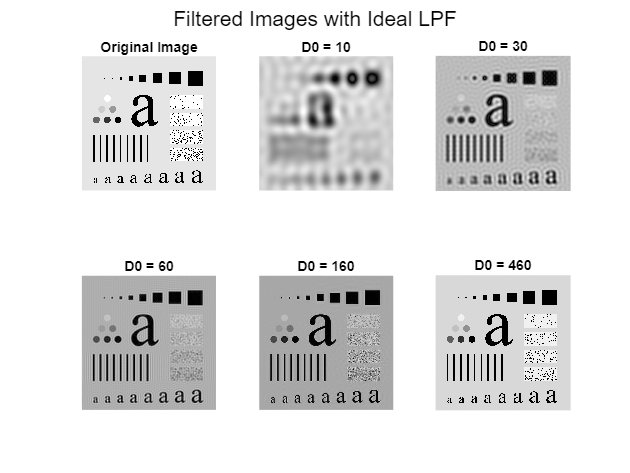

figure;
subplot(2, ceil((length(D0_values) + 1)/2), 1);
imshow(img, []);
title('Original Image');

for i = 1:length(D0_values)
    subplot_index = i + 1;
    D0 = D0_values(i);

    H = double(D <= D0);
    
    img_fft_filtered = H .* img_fft;
    img_filtered = abs(ifft2(ifftshift(img_fft_filtered)));
    
    subplot(2, ceil((length(D0_values) + 1)/2), subplot_index);
    imshow(img_filtered, []);
    title(['D0 = ', num2str(D0)]);
end

sgtitle('Filtered Images with Ideal LPF');